%question_2

%import data
dataset = importdata('/Users/ethanvictormonkhouse/midterm2021.php')

dataset =      1     2     1
     1     2     3
     0     0     1
     0     0     2
     1     2     0
     1     3     0
     0     1     0
     1     2     3
     0     1     3
     1     2     3


[numberOfRows,numberOfColumns]=size(dataset);
fprintf("The dataset contains %d rows, and %d columns. \n", numberOfRows, numberOfColumns);

The dataset contains 1435 rows, and 3 columns. 



%part_a
z_values = (min(dataset(:,2)):max(dataset(:,2)));
probability_2_true = zeros(max(dataset(:,2))+1,1); %define array
probability_2_1_true = zeros(max(dataset(:,2))+1,1); %define array
for i = z_values %calculate quantities for z
    probability_2_1_true(i+1) = sum(dataset(:,2) == i & dataset(:,1) == 1)/numberOfRows; %probability of column1=1 and column2=z
    probability_2_true(i+1) = sum(dataset(:,2) == i )/numberOfRows; %probability of column2=z
end

probability_zi2_given_zi1 = probability_2_1_true./probability_2_true; %probability of column1=1 and column2=z occurring given column1=1

T = table(z_values.', probability_zi2_given_zi1); %create table
T.Properties.VariableNames = {'z', 'E[Zi,1|Zi,2 = z]'} %rename variable columns

T = 4×4 table
    z    E[Zi,1 ∩ Zi,2 = z]    E[Zi,2 = z]    E[Zi,1|Zi,2 = z]
    _    __________________    ___________    ________________

    0                0           0.25784                0     
    1         0.062021           0.24111          0.25723     
    2           0.1993           0.25226          0.79006     
    3          0.24878           0.24878                1     



%part_b

%calculate variance for each z value
variance = zeros(max(dataset(:,2))+1,1); %define array

for i = z_values %iterate through all quantites
    totalSum = 0; %reset totalSum for next quantity
    for j = 1:numberOfRows %iterate through every basket
        if (dataset(j,2) == i) && (dataset(j,1) == 1) %if event Zi2 and event Zi2 occur
            totalSum = totalSum + (1 - probability_zi2_given_zi1(i+1,1))^2; %calculate total sum of expected values minus the expected sample mean, squared
        end
    end
    variance(i+1) = totalSum/numberOfRows; %calculate variance, which is the totalSum divided by the population
end

T = [T table(variance)]; %update table with variance column
T.Properties.VariableNames{'variance'} = 'Variance'; %rename variance column

%calculate variance and confidence intervals
standardError = zeros(max(dataset(:,2))+1,1); %define array
marginError = zeros(max(dataset(:,2))+1,1); %define array
CLTLowerBound = zeros(max(dataset(:,2))+1,1); %define array
CLTUpperBound = zeros(max(dataset(:,2))+1,1); %define array
ChebyshevLowerBound = zeros(max(dataset(:,2))+1,1); %define array
ChebyshevUpperBound = zeros(max(dataset(:,2))+1,1); %define array

for i = z_values %iterate through all quantites
    standardError(i+1) = sqrt(variance(i+1))/sqrt(sum(dataset(:,2) == i)); %SE=standard deviation/sqrt(n)
    marginError(i+1) = sqrt(variance(i+1))/(sqrt(sum(dataset(:,2) == i)*0.05)); %ME.95=standard deviation/sqrt(0.05*n)
    
    CLTLowerBound(i+1) = probability_zi2_given_zi1(i+1) - 2*(standardError(i+1)); %CLT mean - 2(SE)
    CLTUpperBound(i+1) = probability_zi2_given_zi1(i+1) + 2*(standardError(i+1)); %CLT mean + 2(SE)
    
    ChebyshevLowerBound(i+1) = probability_zi2_given_zi1(i+1) - marginError(i+1); %Chebyshev mean - marginOfError
    ChebyshevUpperBound(i+1) = probability_zi2_given_zi1(i+1) + marginError(i+1); %Chebyshev mean + marginOfError
end

T = [T table(CLTLowerBound, CLTUpperBound, ChebyshevLowerBound, ChebyshevUpperBound)]; %update table with variance column
T.Properties.VariableNames({'CLTLowerBound' 'CLTUpperBound' 'ChebyshevLowerBound' 'ChebyshevUpperBound'}) = {'CLT 95% Lower Bound' 'CLT 95% Upper Bound' 'Chebyshev 95% Lower Bound' 'Chebyshev 95% Upper Bound'}

T = 4×9 table
    z    E[Zi,1 ∩ Zi,2 = z]    E[Zi,2 = z]    E[Zi,1|Zi,2 = z]    Variance     CLT 95% Lower Bound    CLT 95% Upper Bound    Chebyshev 95% Lower Bound    Chebyshev 95% Upper Bound
    _    __________________    ___________    ________________    _________    ___________________    ___________________    _________________________    _________________________

    0                0           0.25784                0                 0                0                      0                         0                            0         
    1         0.062021           0.24111          0.25723          0.034218          0.23734                0.27711                   0.212

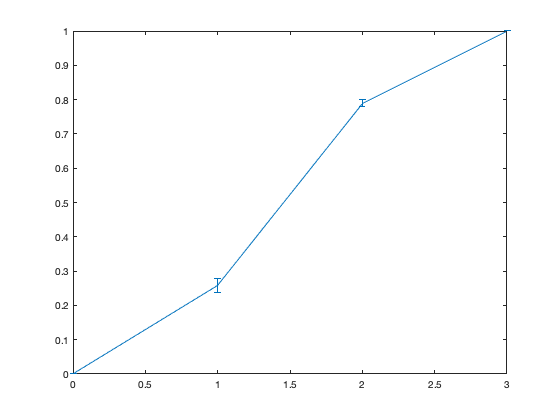


%part_c

errorbar(z_values, probability_zi2_given_zi1, probability_zi2_given_zi1-CLTLowerBound, CLTUpperBound-probability_zi2_given_zi1); %using CLT method

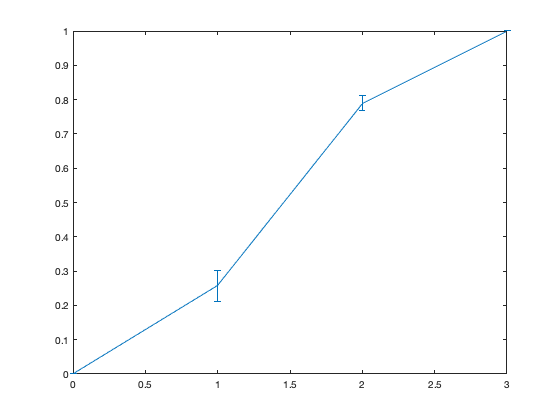

errorbar(z_values, probability_zi2_given_zi1, probability_zi2_given_zi1-ChebyshevLowerBound, ChebyshevUpperBound-probability_zi2_given_zi1); %using Chebyshev method


%question_3

%part_a

